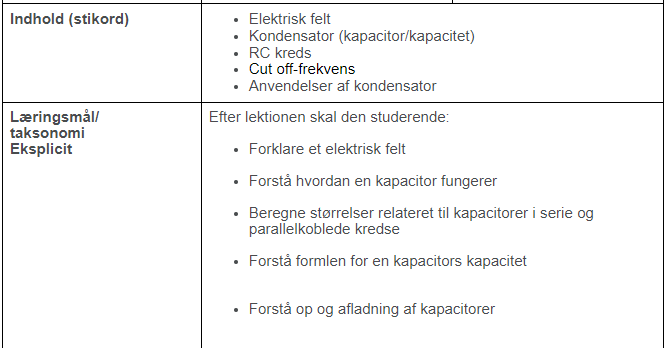

clc; clear;
u = symunit;


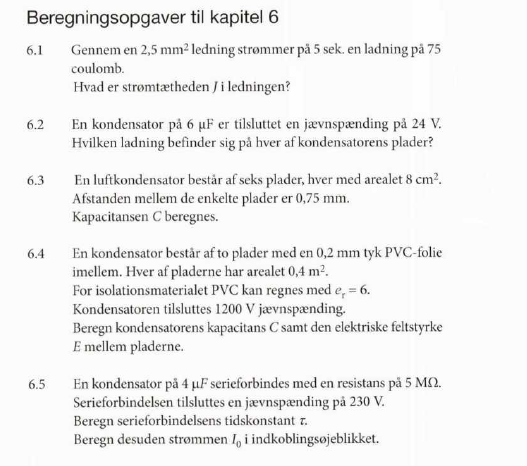

% Opgave 6.1
A = 2.5*u.mm^2;
t = 5*u.s;
Q = 75*u.C;

amps = Q/t % coulomb pr s

$$amps = 15\,\frac{C}{s}$$


D = amps/A

$$D = 6\,\frac{C}{{\mathrm{mm}}^{2}\,s}$$

D = unitConvert(D, "SI")

$$D = 6000000\,\frac{A}{m^{2}}$$

% Opgave 6.2
C = 6*u.mcF;
U = 24*u.V;

% Formel 6.14 bruges
Q = C*U

$$Q = 144\,V\,\mathrm{\mu F}$$

Q = vpa(unitConvert(Q, "SI"),3)

$$Q = 1.44e-4\,A\,s$$

% Opgave 6.3 - luftkondensator
epsilon_luft = 8.85*1e-12 * u.F/u.m;
n = 6;
A = 8*u.cm^2;
d = 0.75*u.mm;

% Beregn kapacitansen - formel 6.16
C = A*epsilon_luft/d * (n - 1)

$$C = \frac{27389423369189035}{58028439341502200385896448}\,\frac{F\,{\mathrm{cm}}^{2}}{m\,\mathrm{mm}}$$

C = vpa(unitConvert(C, "SI"), 3)

$$C = 4.72e-11\,\frac{A^{2}\,s^{4}}{\mathrm{kg}\,m^{2}}$$

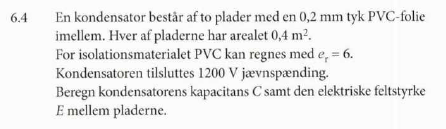

% Opgave 6.4
n = 2;
epsilon_luft = 8.85*1e-12 * u.F/u.m;
t = 0.2*u.mm; % tykkelse af PVC folie
A = 0.4*u.m^2;
e_r = 6;
U = 1200*u.V;

epsilon = epsilon_luft*e_r;

% Kapacitansen - formel under 6.14
C = A*epsilon/t;
C = vpa(unitConvert(C, u.mcF), 3)

$$C = 0.106\,\mathrm{\mu F}$$


% Elektrisk feltstyrke - formel 6.12
E = U/t;
E = unitConvert(E, u.kV/u.m)

$$E = 6000\,\frac{\mathrm{kV}}{m}$$


% Elektrisk feltstyrke igen
Q = C*U;

E2 = Q/(A*epsilon);
E2 = vpa(unitConvert(E2, u.kV/u.m), 3)

$$E2 = 6000.0\,\frac{\mathrm{kV}}{m}$$

% Opgave 6.5
C = 400*u.mcF;
res = 2*u.kohm;
U = 6*u.V;

unitConvert(u.A/u.s,"SI","Derived")

$$ans = \frac{A}{s}$$


% Serieforbindelsens tidskonstant
tau = res*C;
tau = unitConvert(tau,"SI")

$$tau = \frac{4}{5}\,s$$



S = OhmsLawCals([],[],U,res,"ja")

S = struct with fields:
    P: 0.018*[W]
    I: 0.003*[A]
    V: 6.0*[V]
    R: 2000.0*[Ohm]



% Strømmen i indkoblingsøjeblikket
I = S.I;
I = vpa(unitConvert(I, u.mcA), 3)

$$I = 3000.0\,\mathrm{\mu A}$$

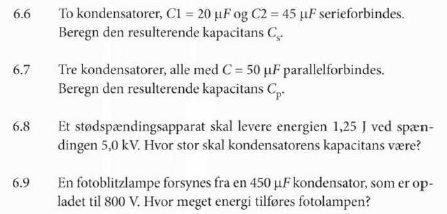

% Opgave 6.6
C1 = 20*u.mcF;
C2 = 45*u.mcF;

C_serie = vpa((1/C1 + 1/C2)^(-1), 5)

% Opgave 6.7
Cs = [50,50,50]*u.mcF;

C_par = sum(Cs)

% Opgave 6.8
E = 1.25*u.J;
U = 5*u.kV;











